# [3.12. Переменный ток (AC)](https://ru.wikipedia.org/wiki/Переменный_ток)

#### Соотношение между частотой, угловой частотой и периодом T

clear
syms f T omega
f==1/T==omega/(2*pi)

$$ans = \left(f=\frac{1}{T}\right)=\frac{\omega }{2\,\pi }$$

#### [Импеданс](https://ru.wikipedia.org/wiki/Электрический_импеданс) и сдвиг фазы напряжения в различных (идеальных) элементах цепи относительно силы тока.

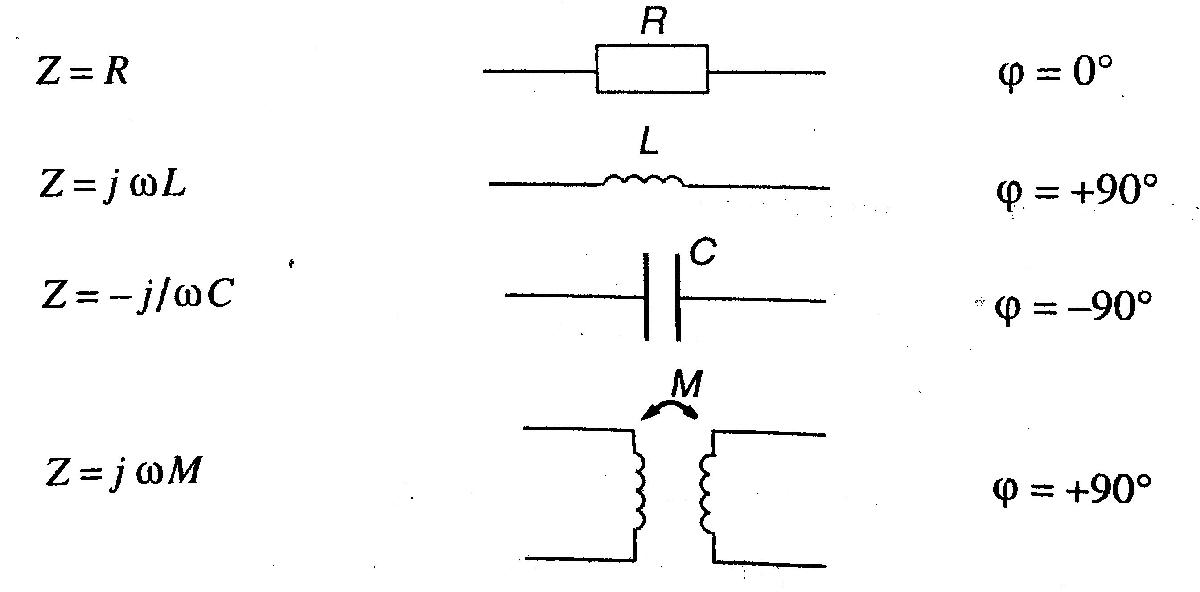

syms Z R phi omega L C  M
Z==R              % phi=0

$$ans = Z=R$$

Z==j*omega*L      % phi=+90

$$ans = Z=L\,\omega \,\mathrm{i}$$

Z==-1j/(omega*L)  % phi=-90

$$ans = Z=-\frac{\mathrm{i}}{L\,\omega }$$

Z==j*omega*M     % phi=+90

$$ans = Z=M\,\omega \,\mathrm{i}$$

% M = взаимоиндуктивность

Общий импеданс

syms Z R X 
Z==R+j*X, phi==atan(X/R)

$$ans = Z=R+X\,\mathrm{i}$$

$$ans = \varphi =\mathrm{atan}\left(\frac{X}{R}\right)$$

#### Полная проводимость

syms Y Z G B
Y==1/Z==G+j*B

$$ans = \left(Y=\frac{1}{Z}\right)=G+B\,\mathrm{i}$$

% G = проводимость
% B = реактивноая проводимость

#### Эффективное значение

syms I T i(r) V v(r)
I==(1/T*int(i^2,r,0,T))^(1/2), V==(1/T*int(v^2,r,0,T))^(1/2)

$$ans = \text{I}=\sqrt{\frac{\int_{0}^{T}{i\left(r\right)}^{2}\mathrm{d}r}{T}}$$

$$ans = V=\sqrt{\frac{\int_{0}^{T}{v\left(r\right)}^{2}\mathrm{d}r}{T}}$$

В частности

syms i i_m omega t I v v_m V
i=i_m*sin(omega*t), I=i_m/sqrt(2)

$$i = i_{m}\,\sin\left(\omega \,t\right)$$

$$I = \frac{\sqrt{2}\,i_{m}}{2}$$

v=v_m*sin(omega*t), V=v_m/sqrt(2)

$$v = v_{m}\,\sin\left(\omega \,t\right)$$

$$V = \frac{\sqrt{2}\,v_{m}}{2}$$

#### Эффективная мощность

syms P V I phi
P==V*I*cos(phi)==R*I^2

$$ans = \left(P=\text{I}\,V\,\cos\left(\varphi \right)\right)={\text{I}}^{2}\,R$$

% cos(phi) = эффективная мощность

#### Реактивная мощность

syms Q V I X
Q==V*I*sin(phi)==X*I^2

$$ans = \left(Q=\text{I}\,V\,\sin\left(\varphi \right)\right)={\text{I}}^{2}\,X$$

#### Полная (кажущаяся) мощность

syms S V I
S==V*I

$$ans = S=\text{I}\,V$$

#### Общее определение добростности


$$Q_0 =\omega_0 \;\frac{\left\langle W_L \right\rangle +\left\langle W_C \right\rangle }{P}$$


syms Q0 omega0 W_L W_C P V_C L avrg(x)
Q0==omega0*(avrg(W_L)+avrg(W_C))/P       % при резонансе

$$ans = Q_{0}=\frac{\omega_{0}\,\left(\mathrm{avrg}\left(W_{C}\right)+\mathrm{avrg}\left(W_{L}\right)\right)}{P}$$

% omega0 = угловая частота при резонансе
% <W_L> и <W_C> - средние по времени значения накоплений
% энергии в катушках индуктивности и в конденсаторах


$$\left\langle W_L \right\rangle =\frac{1}{2}L\;I^2$$



$$\left\langle W_C \right\rangle =\frac{1}{2}C\;V_C^2$$


avrg(W_L)==1/2*L*I^2, avrg(W_C)==1/2*C*V_C^2

$$ans = \mathrm{avrg}\left(W_{L}\right)=\frac{{\text{I}}^{2}\,L}{2}$$

$$ans = \mathrm{avrg}\left(W_{C}\right)=\frac{C\,{V_{C}}^{2}}{2}$$

#### [Мост Уитстона](https://ru.wikipedia.org/wiki/Измерительный_мост)

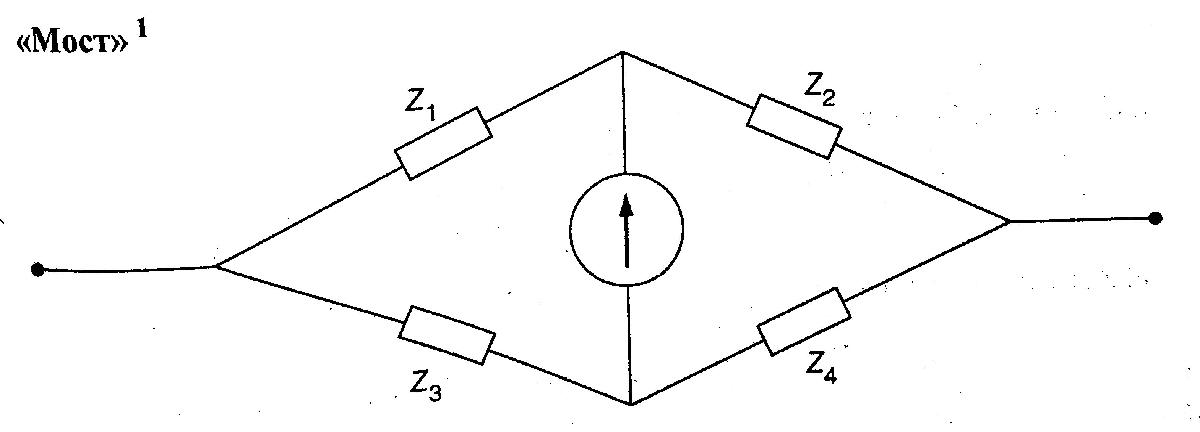

Условие баланса

syms Z1 Z2 Z3 Z4
Z1*Z4 == Z2*Z3

$$ans = Z_{1}\,Z_{4}=Z_{2}\,Z_{3}$$

#### Регулировка мощности

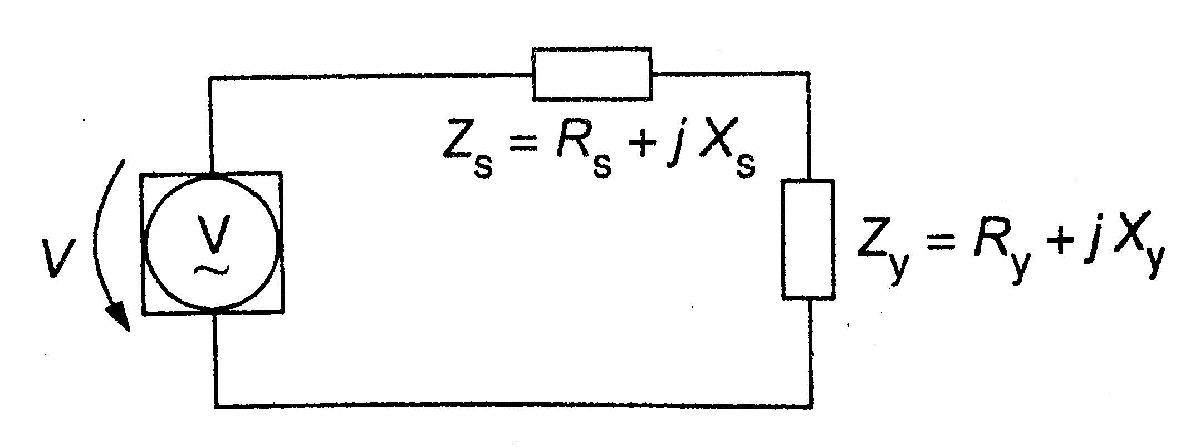

syms P_y R_y V R_s X_s X_y
P_y==R_y*V^2/((R_s+R_y)^2+(X_s+X_y)^2)

$$ans = P_{y}=\frac{R_{y}\,V^{2}}{{\left(R_{s}+R_{y}\right)}^{2}+{\left(X_{s}+X_{y}\right)}^{2}}$$

Условие максимальной мощности для Z_y

syms P_max
R_y==R_s, X_y==-X_s  % =>

$$ans = R_{y}=R_{s}$$

$$ans = X_{y}=-X_{s}$$

P_max==V^2/(4*R_s)

$$ans = P_{\max}=\frac{V^{2}}{4\,R_{s}}$$

% если R_y и X_y могут быть выбраны независимо

syms Z_y Z_s V R_y V phi_y phi_s
abs(Z_y)==abs(Z_s) % =>

$$ans = \left|Z_{y}\right|=\left|Z_{s}\right|$$

P_max==V^2*R_y/abs(Z_s+Z_y)^2==V^2*cos(phi_y)/(2*abs(Z_s)*(1+cos(phi_y-phi_s)))

$$ans = \left(P_{\max}=\frac{R_{y}\,V^{2}}{{\left|Z_{s}+Z_{y}\right|}^{2}}\right)=\frac{V^{2}\,\cos\left(\varphi_{y}\right)}{2\,\left|Z_{s}\right|\,\left(\cos\left(\varphi_{s}-\varphi_{y}\right)+1\right)}$$

% если только величина Z_y может быть переменной (напр. резистор)
phi_y==atan(X_y/R_y), phi_s==atan(X_s/R_s)

$$ans = \varphi_{y}=\mathrm{atan}\left(\frac{X_{y}}{R_{y}}\right)$$

$$ans = \varphi_{s}=\mathrm{atan}\left(\frac{X_{s}}{R_{s}}\right)$$

R_y==abs(Z_y)*cos(phi_y), R_s==abs(Z_s)*cos(phi_s)

$$ans = R_{y}=\left|Z_{y}\right|\,\cos\left(\varphi_{y}\right)$$

$$ans = R_{s}=\left|Z_{s}\right|\,\cos\left(\varphi_{s}\right)$$